% Author: Gerardo Parra
clear

%% parameters for running batch script
% parameters for loading data
task      = 'tss';
beapp_tag = '_25hzLP_32hzNF';
file_tag  = [beapp_tag '_2023-04-28_gp'];
data_path = fullfile( 'X:','Groups','SPA','01_Data_Raw_Summary_Processed', ...
                      'EEG','Participant_Data','03_Processed_Data' );

% parameters for processing
method    = 'conds_avg';
rois      = {'E30E36E41'};
groups    = {'TD','ASD','SPC'};
exclude   = {'1046'};
% erps      = {'P50','P100','P100_N140_dist','N140_P300_dist','P300','P4'};
% erp_times = [50 100 175 275 300 400];
erps      = {'P50','N140','P100','P300'};
erp_times  = [50 100 300];
% parameters for plots
save_figs  = true;
norm_data  = false;
cond_names = {'Index','Middle','Both'};
colors  = {'#4444c9','#32a852','#e69a0e'};
markers = {'o','+','*'};

  

%% load batch information
task_path = get_task_path(task);
task_path_batch = fullfile(data_path,task_path,'erp',['erp' file_tag '.mat']);
load(task_path_batch,'batch');
if norm_data, method = [method '_norm']; end
batch.method = method;
% get save path
save_path = fullfile(data_path,task_path,'figures','erp_indiv');
if ~exist(save_path,'dir'), mkdir(save_path); end

% calculate or load group averages
[data,batch] = calc_si_by_indiv(batch,exclude,erps,1);

p = 0.0154

mw = 0.0123

d = 1.0186

p = 0.0173

mw = 0.0157

d = -0.9990

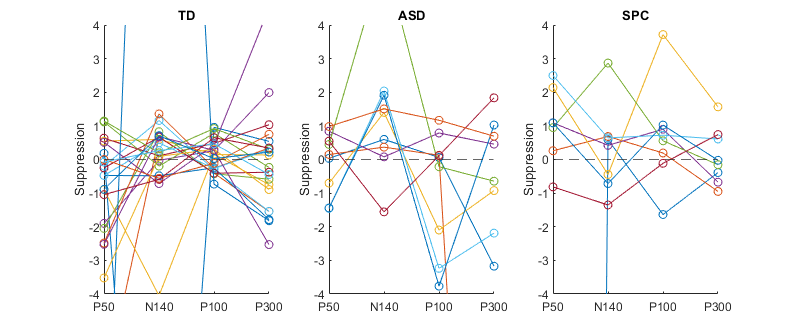

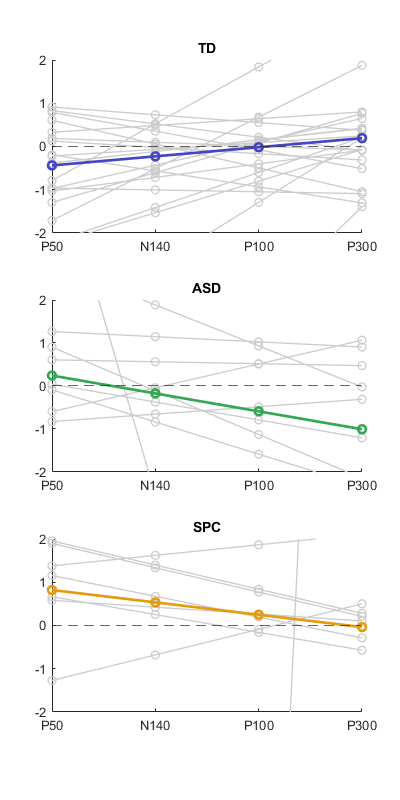

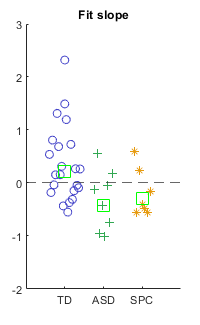

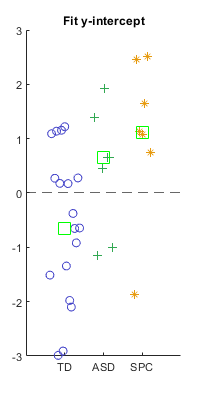

% iterate through group
n_grps = length(groups); 
n_rois = length(rois);
n_erps = length(erps);
for i_r = 1:n_rois
    roi = rois{i_r};
    % plot individual erps
    f_raw_slope = figure('Position',[50 50 1000 375]);
    ax     = zeros(n_grps);
    slopes = [];
    for i_g = 1:n_grps
        grp    = groups{i_g};
        subjs  = fieldnames(data.(grp).(roi));
        n_subj = length(subjs);
        subplot(1,n_grps,i_g), hold on
        for i_s = 1:n_subj
            subj = subjs{i_s};
            subj_data = data.(grp).(roi).(subj);
            subj_fit_pk_ct = polyfit(1:n_erps,subj_data,1);
%             subj_fit_time  = polyfit(erp_times,subj_data,1);
            % add subject row to struct
            slopes(end+1).id  = str2double(subj(2:end));
            slopes(end).group = i_g;
            slopes(end).m_pk_ct = subj_fit_pk_ct(1);
            slopes(end).b_pk_ct = subj_fit_pk_ct(2);
%             slopes(end).m_time  = subj_fit_time(1);
%             slopes(end).b_time  = subj_fit_time(2);
            plot(subj_data,'-o')
        end
        ax(i_g) = gca;
        xticks(1:length(erps)); xticklabels(plaintext(erps)), ylim([-4 4])
        title(grp); ylabel('Suppression'); yline(0,'--')
    end
    linkaxes(ax)
    
    % plot average SI slopes (by peak count)
    all_coeffs_pks  = [slopes.group; slopes.m_pk_ct; slopes.b_pk_ct]';
    grp_coeffs_pks  = cell(n_grps,1);
%     all_coeffs_time = [slopes.group; slopes.m_time; slopes.b_time]';
%     grp_coeffs_time = cell(n_grps,1);
    f_fit_funcs = figure('Position',[250 50 400 1000]); hold on, s = [];
    for i_g = 1:n_grps
        s(end+1) = subplot(n_grps,1,i_g); hold on
        % get group coefficients and average
        grp_coeffs_pks{i_g} = all_coeffs_pks(all_coeffs_pks(:,1) == i_g,2:3);
        grp_coeff_avg = median(grp_coeffs_pks{i_g},1,'omitnan');
        % plot individuals from group
        grp_n = size(grp_coeffs_pks{i_g},1);
        for i_s = 1:grp_n
            plot(polyval(grp_coeffs_pks{i_g}(i_s,:),1:n_erps),'-o','LineWidth',1,'Color','#ccc')
        end
        % plot group average and add to legend
        plot(polyval(grp_coeff_avg,1:n_erps),'o-','LineWidth',2,'Color',colors{i_g})
        title([groups{i_g}])% ', n=' int2str(grp_n)])
        xticks(1:n_erps), xticklabels(plaintext(erps)), yline(0,'--'), ylim([-2 2])
    end
    linkaxes(s)
   
    %% scatter plots of coefficients (by peak count)
    % plot slopes
    f_fit_slope = figure('Position',[250 50 200 325]); hold on, title('Fit slope')
    plotSpread(cellfun(@(x) x(:,1),grp_coeffs_pks,'UniformOutput',false),'showMM',3, ...
                    'distributionMarkers',markers,'distributionColors',colors)
    yline(0,'--'), xticks(1:n_grps), xticklabels(groups), ylim([-2 3])
    [~,p] = ttest2(grp_coeffs_pks{1}(:,1),grp_coeffs_pks{2}(:,1))
    [mw,~] = ranksum(grp_coeffs_pks{1}(:,1),grp_coeffs_pks{2}(:,1))
    d = computeCohen_d(grp_coeffs_pks{1}(:,1),grp_coeffs_pks{2}(:,1))
    
    % plot y intercepts
    f_fit_y = figure('Position',[250 50 200 400]); hold on, title('Fit y-intercept')
    plotSpread(cellfun(@(x) x(:,2),grp_coeffs_pks,'UniformOutput',false),'showMM',3, ...
                    'distributionMarkers',markers,'distributionColors',colors)
    yline(0,'--'), xticks(1:n_grps), xticklabels(groups), ylim([-3 3])
    [~,p] = ttest2(grp_coeffs_pks{1}(:,2),grp_coeffs_pks{2}(:,2))
    [mw,~] = ranksum(grp_coeffs_pks{1}(:,2),grp_coeffs_pks{2}(:,2))
    d = computeCohen_d(grp_coeffs_pks{1}(:,2),grp_coeffs_pks{2}(:,2))
    
    %% scatter plots of coefficients (by time)
%     % plot average SI slopes (by time)
%     figure, hold on, s = [];
%     for i_g = 1:n_grps
%         s(end+1) = subplot(n_grps,1,i_g); hold on
%         % get group coefficients and average
%         grp_coeffs_time{i_g} = all_coeffs_time(all_coeffs_time(:,1) == i_g,2:3);
%         grp_coeff_avg = median(grp_coeffs_time{i_g},1,'omitnan');
%         % plot group average and add to legend
%         plot(polyval(grp_coeff_avg,0:max(erp_times)),'-','LineWidth',2,'Color',colors{i_g})
%         % plot individuals from group
%         grp_n = size(grp_coeffs_pks{i_g},1);
%         for i_s = 1:size(grp_coeffs_time{i_g},1)
%             plot(polyval(grp_coeffs_time{i_g}(i_s,:),0:max(erp_times)),':','LineWidth',1,'Color',colors{i_g})
%         end
%         title([groups{i_g} ', n=' int2str(grp_n)]), yline([0 1],'--','DisplayName','')
%         xticks(erp_times), xticklabels(plaintext(erps)), ylim([-3 3])
%     end
%     linkaxes(s), sgtitle([roi ' Suppression across ERPs (Time)'])
%     % plot slopes
%     figure, hold on, title('Fit slope (time)')
%     plotSpread(cellfun(@(x) x(:,1),grp_coeffs_time,'UniformOutput',false),'showMM',3, ...
%                     'distributionMarkers','o','distributionColors',colors)
%     yline(0,'--'), xticks(1:n_grps), xticklabels(groups), ylim([-3 3])
%     
%     % plot y intercepts
%     figure, hold on, title('Fit y-intercept (time)')
%     plotSpread(cellfun(@(x) x(:,2),grp_coeffs_time,'UniformOutput',false),'showMM',3, ...
%                     'distributionMarkers','o','distributionColors',colors)
%     yline(0,'--'), xticks(1:n_grps), xticklabels(groups), ylim([-3 3])
    
    
    if save_figs
        saveas(f_raw_slope,fullfile(save_path,[roi '_raw_slope' file_tag]),'jpg')
        exportgraphics(f_fit_funcs,fullfile(save_path,[roi '_fit_func' file_tag '.jpg']),'Resolution',300)
        exportgraphics(f_fit_slope,fullfile(save_path,[roi '_fit_slope' file_tag '.jpg']),'Resolution',300)
        saveas(f_fit_y,fullfile(save_path,[roi '_fit_y' file_tag]),'jpg')
    end
end